C = 0.08;
A = 1.0;
B = 0.2;
D = 0.9;
IO = 1;
tStart = 40;
tStop = 47;
I = @(t)IO*(t>tStart).*(t<tStop);

    f1 =@(V1,V2,V3,W,t) V1 - 1/3*V1^3-W+D*(V2-2*V1+V3)

f1 = function_handle with value:
    @(V1,V2,V3,W,t)V1-1/3*V1^3-W+D*(V2-2*V1+V3)


    f2 =@(V,W,t) C*(V+A-B*W);
    f3=@(V1,V2,V3,W,t) V1 - 1/3*V1^3+I(t)-W*D*(V2-2*V1+V3)

f3 = function_handle with value:
    @(V1,V2,V3,W,t)V1-1/3*V1^3+I(t)-W*D*(V2-2*V1+V3)


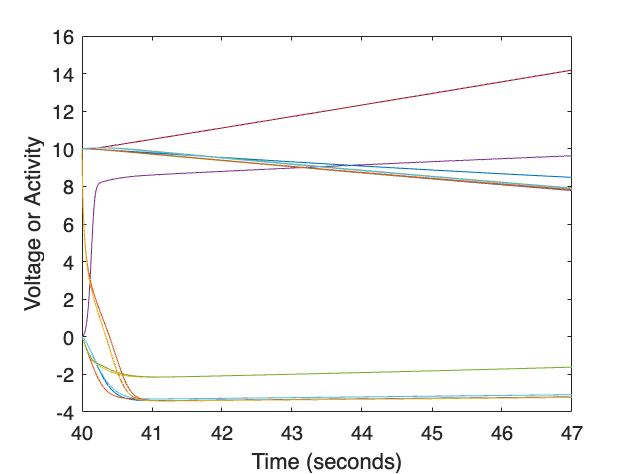



dxdt = @(t,x)[f1(x(1),x(10), x(2),x(11), t);
              f1(x(2),x(1), x(3),x(12), t);
              f1(x(3),x(2), x(4),x(13), t);
              f3(x(4),x(3), x(5),x(14), t);
              f1(x(5),x(4), x(6),x(15), t);
              f1(x(6),x(5), x(7),x(16), t);
              f1(x(7),x(6), x(8),x(17), t);
              f1(x(8),x(7), x(9),x(18), t); 
              f1(x(9),x(8), x(10),x(19), t); 
              f1(x(10),x(9), x(1),x(20), t);
              f2(x(1),x(11),t);
              f2(x(2),x(12),t);
              f2(x(3),x(13),t);
              f2(x(4),x(14),t);
              f2(x(5),x(15),t);
              f2(x(6),x(16),t);
              f2(x(7),x(17),t);
              f2(x(8),x(18),t);
              f2(x(9),x(19),t);
              f2(x(10),x(20),t)];
 

[T, X] = ode45(dxdt, [40,47], [0,0,0,0,0,0,10,10,10,10,10,10,10,10,10,10,10,10,10,10]);

plot(T,X)
ylabel('Voltage or Activity')
xlabel('Time (seconds)')

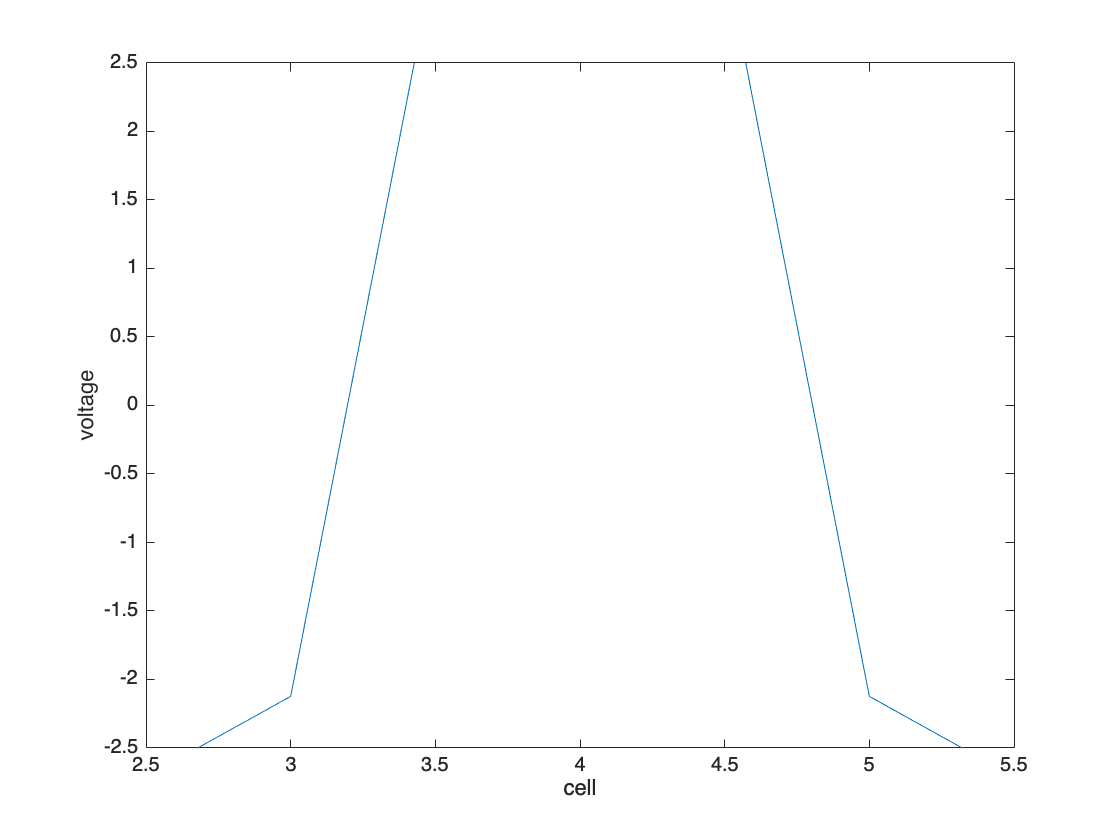


for nt=1:numel(T)
    figure(5); clf; hold on; box on;
    plot (X(nt,1:10));
    set(gca,'ylim',[-2.5,2.5])
    xlabel('cell');
    ylabel('voltage');
    drawnow;
end